# Homework #5. 

## Problem 1 (15 points)

Consider the equilibrium equations for a Wilberforce double pendulum

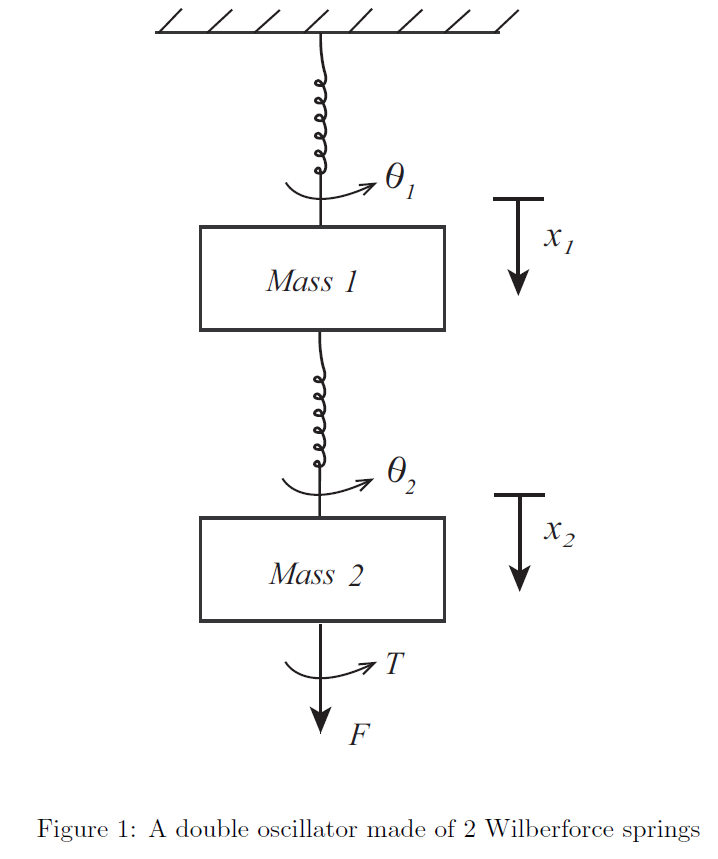

which can be written in the form

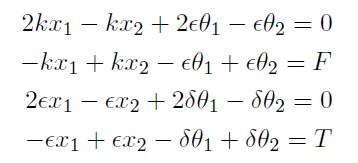

where $x_1$, $x_2$ denote the locations of masses 1 and 2 in the vertical direction, respectively, $\theta_1$ and $\theta_2$ denote the rotation of masses 1 and 2, *F* is the externally applied force exerted on mass 2, and *T* is the externally applied torque exerted on mass 2, as shown in the Fig. 1. All coordinates are measured from the equilibrium position defined by *F = 0* and *T = 0. *

This system of equations can be written in the matrix form *Ku *= *f* where *u *= ${\left\lbrack x_1 ,x_2 ,\theta_1 ,\theta_2 \right\rbrack }^T$, *f* = ${\left\lbrack 0,F,0,T\right\rbrack }^T$, and *K* is a `4x4` matrix. 

a) (5 points) Form a stiffness matrix K for the case where parameters of the springs are *k *= 4 N/m, $\delta$ = 2 Nm, $\epsilon$ = 1 N.

% Your code here
k = 4;
del = 2;
er = 1;
K = [2*k -k 2*er -er; -k k -er er; 2*er -er 2*del -del; -er er -del del;]

K =      8    -4     2    -1
    -4     4    -1     1
     2    -1     4    -2
    -1     1    -2     2


b) (2 points) Form a vector for the case where the externally applied loads are  *F *= 2 N and *T *= 1 Nm and store it in a 2x1 vector named f. 

% Your code here
f = [0; 2; 0; 1;]

f =      0
     2
     0
     1


c) (2 points) Solve the system of equations  *Ku *= *f* for the unknown displacements & rotations in vector *u *and store it in a 2x1 vector named u.

% Your code here
u = K\f

u =     0.4286
    0.8571
    0.2857
    0.5714


d) (2 points) Form a vector for the case where the externally applied loads are  *F *=0.5 N and *T *= 3 Nm and store it in a 2x1 vector named q. 

% Your code here
q = [0; 0.5; 0; 3;]

q =          0
    0.5000
         0
    3.0000


e) (2 points) Solve the system of equations  *Kp *= *q* for the unknown displacements & rotations in vector *p *and store it in a 2x1 vector named p.

% Your code here
p = K\q

p =    -0.2857
   -0.5714
    1.6429
    3.2857


f) (2 points) Is it true that  *K(u+p) *= (*f+q)* in this case?  Is this true more generally (for any matrix K, for any right hand side vectors *f* and *q*)? 

% Your code here to check if K(u+p) = (f+q) 
sameness = K*(u+p)==(f+q)

sameness = 4×1 logical array
   1
   1
   1
   1


% Your comment here about its generality
% K*u = f; K*p = q; and since matrix multiplication has the distributive
% property of equality K*(u+p) = K*u + K*p

## Problem 2 (30 points) 

Write a function `g_e` (header provided at the bottom) that takes as input an `nxn` matrix $A$ of rank($A$)=n and an `nx1` vector $b$ defining the system of equations $A\;x=b$ and returns the upper triangular matrix $U$ and new right-hand-side vector $\hat{b}$ such that the system of equations is equivalent to $A\;x=b$ , that is, that $U\;x=\hat{b}$ is guaranteed to have the same solution $x$ that satisfies $A\;x=b$ .  

*NOTE:* You may assume that row pivoting will not be required. Do not use the "\" operator or any other MATLAB built-in inside your function. 


% Test your function here
% It would be a fine idea to test g_e of K and f from problem 1
xRef = K\f;
[U f_hat] = g_e(K,f);
abs(U\f_hat - xRef)<10^-12

ans = 4×1 logical array
   1
   1
   1
   1


## Problem 3 (15 points) 

Write a function `b_s` (header provided at the bottom) that takes as input an `nxn` upper-triangular matrix *U* and the corresponding `nx1` vector $\hat{f}$ and returns the `nx1` vector *u *(see Problem 2). Note that you can confirm that your solution is correct by comparing it to the MATLAB result` u=K\f`.

*NOTE:* Do not use the "\" operator or any other MATLAB built-in inside your function.

% Test your function here
u=b_s(U,f_hat);
abs(u - K\f)<10^-12

ans = 4×1 logical array
   1
   1
   1
   1


## Problem 4 (25 points) 

In this problem we will explore the cost of solving the linear system *Au *= *b* using the MATLAB backslash operator "\".  Let *A* be a `(m+1)x(m+1)`,  sparse matrix. The code block below defines this matrix in two guises: first by declaring it as a sparse matrix (referred to as `As`) and second by not declaring it as a sparse matrix (referred to as `A`). The vector `b` is also defined.

a) (15 points) You are asked to solve the system of equations for the unknown *u* using four different approaches:

- Using matrix `A` and the MATLAB `inv()` operator.

- Using matrix `As` and the MATLAB `inv()` operator.

- Using matrix `A` and the MATLAB `'\'` operator.

- Using matrix `As` and the MATLAB `'\'` operator.

For each of these, plot (using `loglog`) the computational time of calculating the solution vector *u* as function of `m`, using  `m=[500, 1000, 2500, 10000]`, and put all four plots on the same figure. Comment on your observations. In particular, compare your results with what you would expect for the cost of these operations based on your knowledge of the structure of `A` and `As` and the algorithms used.

Note that the cost of some of these solutions will be high for `m>1000`. For this reason, it is recommended that you write, test, and "debug" your code using low values of `m`. Only run your code for `m>1000` for your final, "production" runs. Also, the time taken when using `'\'` on `As` will be sufficiently short that this calculation will need to be repeated a number of times (~ 100 times) and an average number provided. 

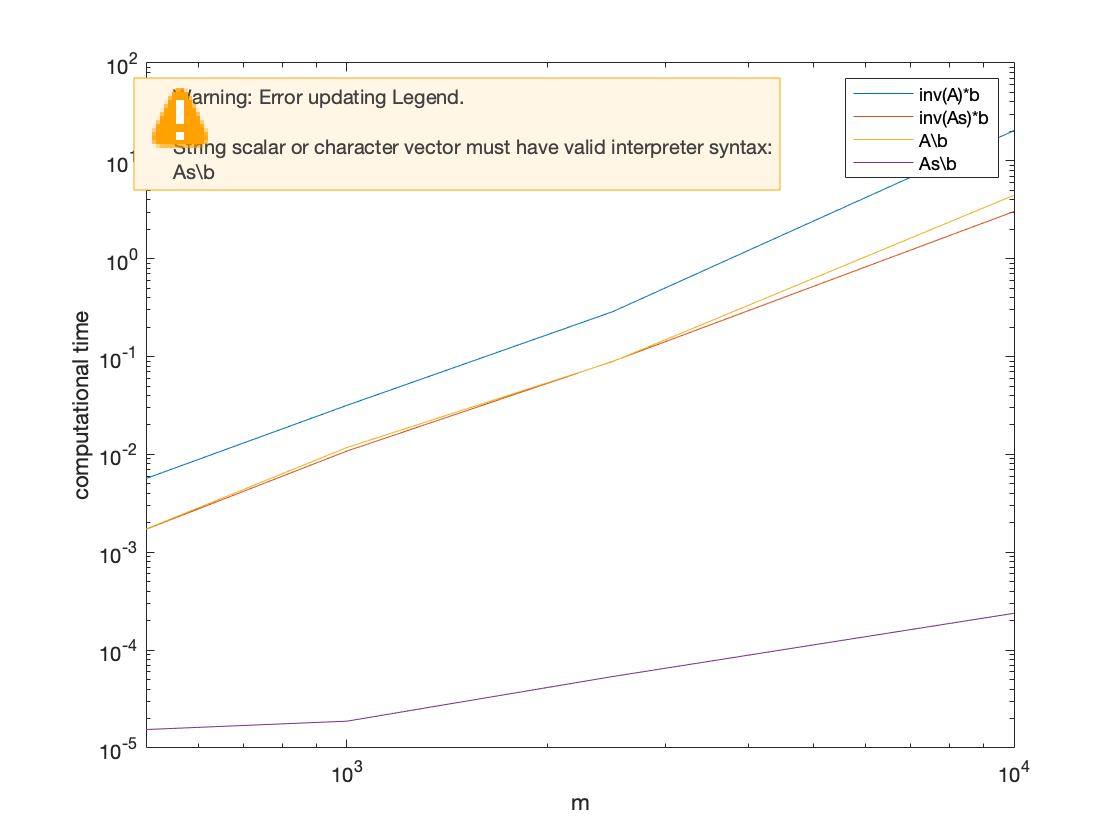

clear
close all
m=[500, 1000, 2500, 10000];
m_lng=length(m); % size of m
t=zeros(4,m_lng); % timing matrix
for i=1:m_lng
A=diag(-2*ones(m(i)+1,1),0) + diag(ones(m(i),1),1) + diag(ones(m(i),1),-1);
As= sparse(diag(-2*ones(m(i)+1,1),0) + diag(ones(m(i),1),1) + diag(ones(m(i),1),-1));
b=10*randn(m(i)+1,1);
% Provide your code here (this code may take up to a few minutes to run; be patient!)
tic
u1 = inv(A)*b;
t(1,i) = toc;
tic
u2 = inv(As)*b;
t(2,i) = toc;
tic
u3 = A\b;
t(3,i) = toc;
t4sum = 0;
trials=100;
tic
for j=1:trials
    u4 = As\b;
end
t(4,i) = toc/trials;
end
% Provide your plot here
loglog(m,t(1,:))
hold on
loglog(m,t(2,:))
loglog(m,t(3,:))
loglog(m,t(4,:))
legend('inv(A)*b','inv(As)*b','A\b','As\b')
xlabel('m')
ylabel('computational time')


% Provide your comments here
% t(1,i)corresponds to the times it takes to calculate inv(A)*b for the respective m(i)
% t(2,i)corresponds to the times it takes to calculate inv(As)*b for the respective m(i)
% t(3,i)corresponds to the times it takes to calculate A\b for the respective m(i)
% t(4,i)corresponds to the times it takes to calculate As\b for the respective m(i), with the time being an average of 100 trials
% the time it takes to calculate an As operation is much smaller than the
% respective A operation
% inv() takes  more time to calculate than \
% as the matrix increases in size, the computation time increases
% the inv() operation and A\b has the cost O(n^3) and As\b has the cost O(n)

b) (10 points) Let the sparsity score of a matrix be defined as the number of zero entries in the matrix divided by the total number of matrix elements. Calculate the sparsity score for `A`, `As`, `inv(A)`, and `inv(As)` for `m=500` and report it in `A_score`, `As_score`, `inv_A_score`, and `inv_As_score`, respectively. In a comment block below your answers discuss the following: How did the sparsity score change after the matrix inversion? Does declaring a matrix as sparse have an effect on its sparsity score after inversion? Use your knowledge of the structure of `A` and `As` to explain the four different scores obtained. Be as quantitative as possible (in some cases it is possible to write expressions for this score as a function of `m`). 

clear
m=500;
A=diag(-2*ones(m+1,1),0) + diag(ones(m,1),1) + diag(ones(m,1),-1);
As= sparse(diag(-2*ones(m+1,1),0) + diag(ones(m,1),1) + diag(ones(m,1),-1));
% Insert your code below
tot_num = (m+1)*(m+1);
A_score = length(find(~A))/tot_num

A_score = 0.9940

As_score = length(find(~As))/tot_num

As_score = 0.9940

inv_A = inv(A);
inv_As = inv(As);
inv_A_score = length(find(~inv_A))/tot_num

inv_A_score = 0

inv_As_score = length(find(~inv_As))/tot_num

inv_As_score = 0

%Provide your comments here
% for A and As, the score is 1 - (3m-1)/(m+1)^2, because the band width is
% always 3 and the matrix size is always m+1, m+1
% the inverse A and inverse As score would always be zero because they do
% not have any zero elements

## Problem 5 (15 points) 

This problem relates to the "Baby Yoda" depicted in a plot below.  You will need the "stereolithography" (.stl) document called upon in the code below from the Canvas site (BabyYoda.stl).  Place the stl doc in the same file where you are running this live script.  If you do that, the code below will generate a plot of the Baby Yoda that you worked with in HW4 except this time as a solid body rather than a point cloud. 

This geometry is described by vB and fB.  The matrix vB has three columns and 208,496 rows describing the vertices of the Baby Yoda.  For example vB(i,1) is the x location of the ith vertex, vB(i,2) is the y location of the ith vertex, and vB(i,3) is z location of the ith vertex. The matrix fB has three columns and 415,902 rows describing the faces of the Baby Yoda.  For example fB(j,:) has three columns with the indices of three vertices belonging to the jth face (tiny little triangle) covering the surface of this object.

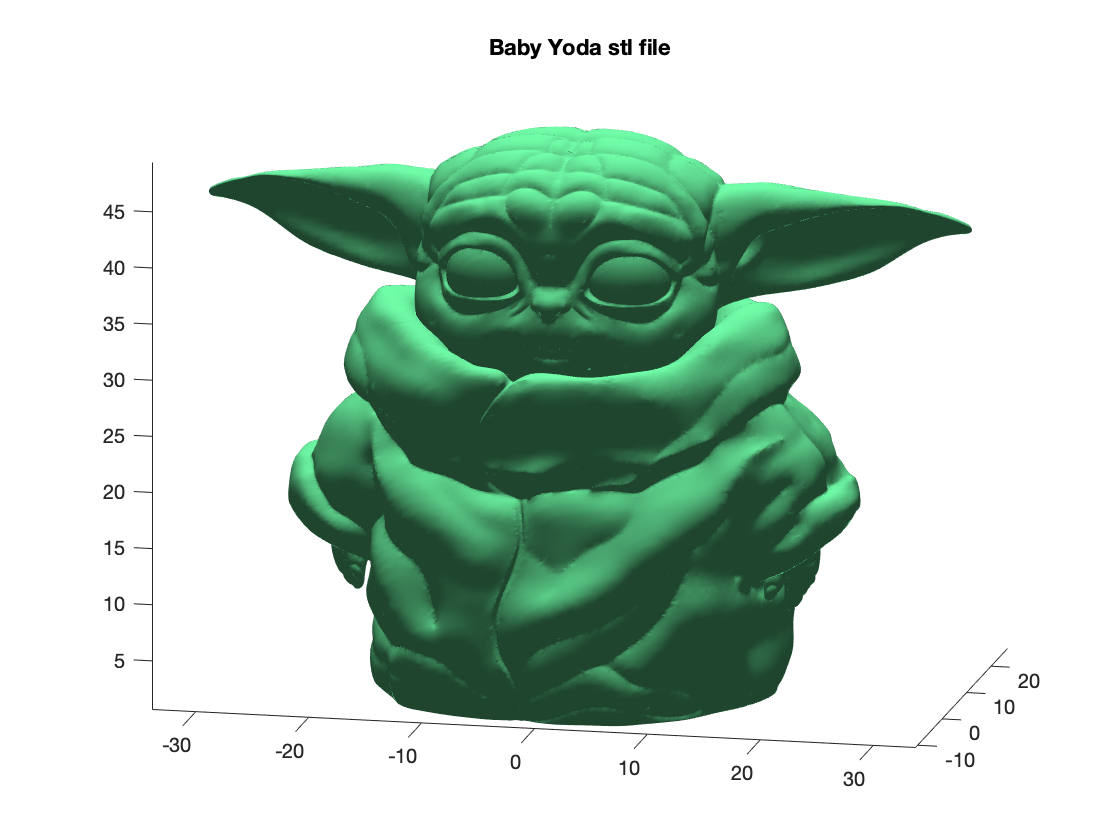

clear all
close all
% Read in the Baby Yoda stl
[vB, fB]=stlReadBinary('BabyYoda.stl');
stlPlot(vB,fB,[0.7 0.7 0.9])
title("Baby Yoda stl file")
view([12.1 13.5])

a) (2 points) One of the vertices in the Baby Yoda near the tip of his right ear (on your left if you're facing Yoda) has an index of 195.  Let's say that Baby Yoda receives an innoculation at that location.  Plot a red dot on that vertex so that we can see the injection site.

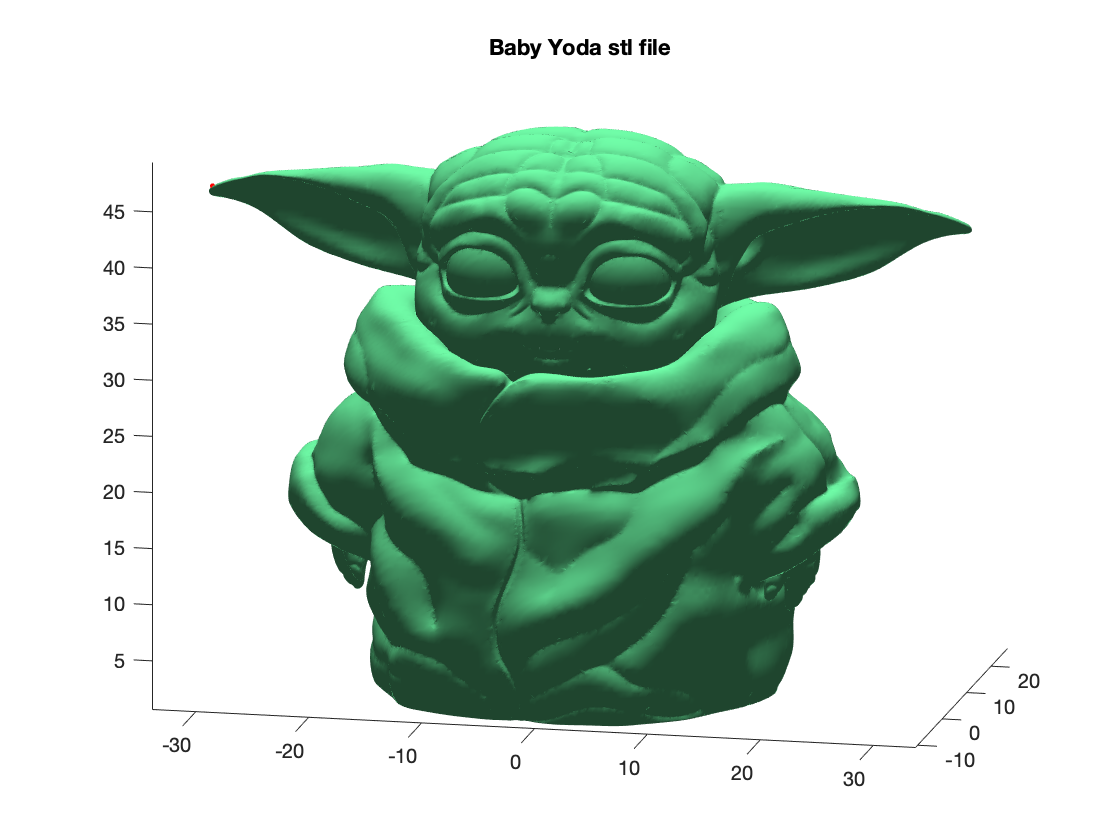

% Your code here:
clear all
close all
[vB, fB]=stlReadBinary('BabyYoda.stl');
stlPlot(vB,fB,[0.7 0.7 0.9])
title("Baby Yoda stl file")
view([12.1 13.5])
hold on
injection_site=195;
injection_point = vB(195,:);
plot3(injection_point(1),injection_point(2),injection_point(3),'r.');

b) (2 points) The vertex at the injection site is part of seven faces defining Baby Yoda's skin.  Provide a list of the faces (identified by row numbers within fB) that include the injection site and return them in a 5x1 vector "Faces_adjacent".

% Your code here
[row,col] = find(fB==195);
Faces_adjacent = row

Faces_adjacent =       315495
      315497
      315504
      319270
      319271


c) (3 points) Write a function called RedWeb (header provided below) that will plot red lines around a set of faces given a list of row numbers corresponding to those faces and a list of all the vertices and their corresponding coordinates and a list of the faces that make up the body.  Use the function to show the injection flow in one time interval by plotting RedWeb(Faces_adjacent,vB,fB,[1 0 0]).  It will help if your plot command also sets the axis limits tight around the points and if we set a better viewing angle as implemeted below. 

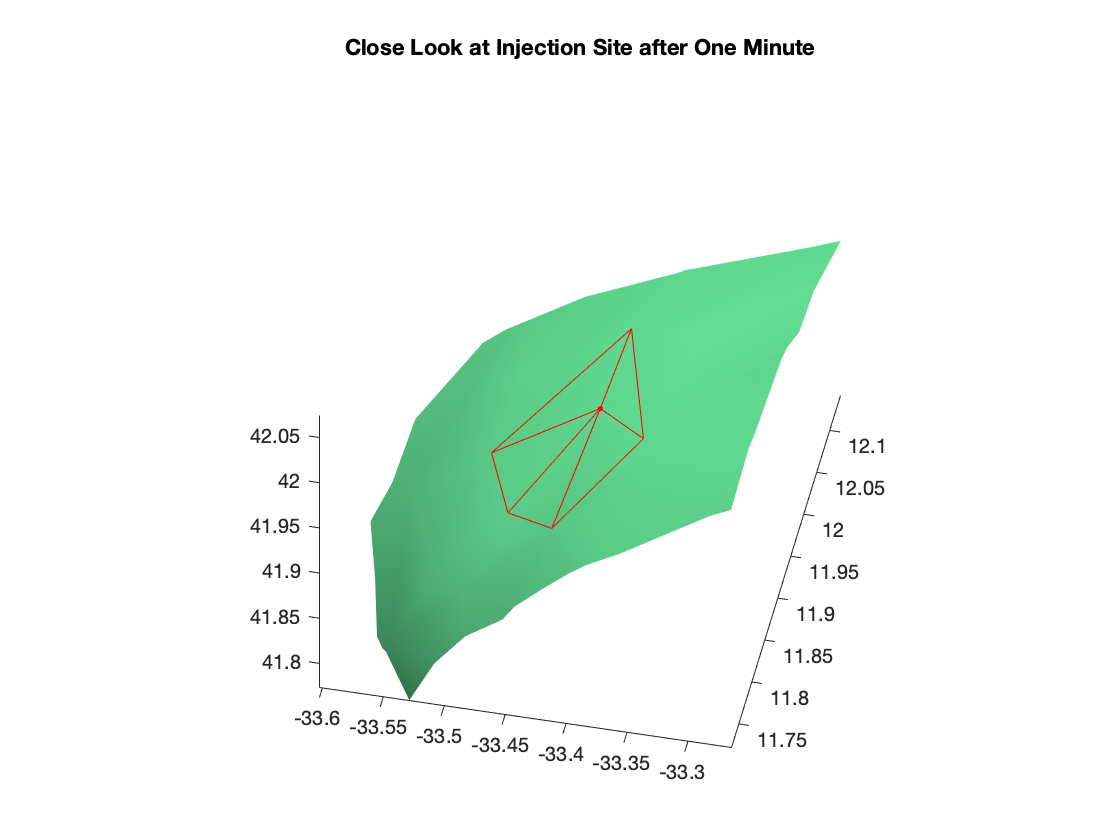

% Your code here
RedWeb(Faces_adjacent,vB,fB,[1 0 0])
eps=0.1;
xlim([min(vB(fB(Faces_adjacent),1))-eps max(vB(fB(Faces_adjacent),1))+eps])
ylim([min(vB(fB(Faces_adjacent),2))-eps max(vB(fB(Faces_adjacent),2))+eps])
zlim([min(vB(fB(Faces_adjacent),3))-eps max(vB(fB(Faces_adjacent),3))+eps])
view([12.1 43.5])
title('Close Look at Injection Site after One Minute')

d) (3 points) The five faces from part (b) (aka "Faces_adjacent") contain vertices that are also are members of other, new faces. Provide a list of the rows numbers in fB that contain any of the three values contained in "Faces_adjacent".  Place these row numbers in column vector named "Faces_neighboring".  Please ensure that the set "Faces_neighboring" does not include any members of "Faces_adjacent" so that we include only new locations for the injection to spread.

% Your code here
Faces_neighboring=find_neighbor(Faces_adjacent,fB,vB,[])

Faces_neighboring =       311793      311794      311797      311801      311802      315496      315498      315499      315500      315505      315506      319263      319267      319268      319269      319275      319276      319277      319278      319279      319280      319281      322916


e) (1 point) Use the function called RedWeb to visualize the progress of the vaccination.  Make the lines in the neighboring sites less bright red than those adjacent to the injection site.  You can do this by plotting RedWeb(Faces_neighboring,vB,fB,[0.6 0.4 0.4]).   

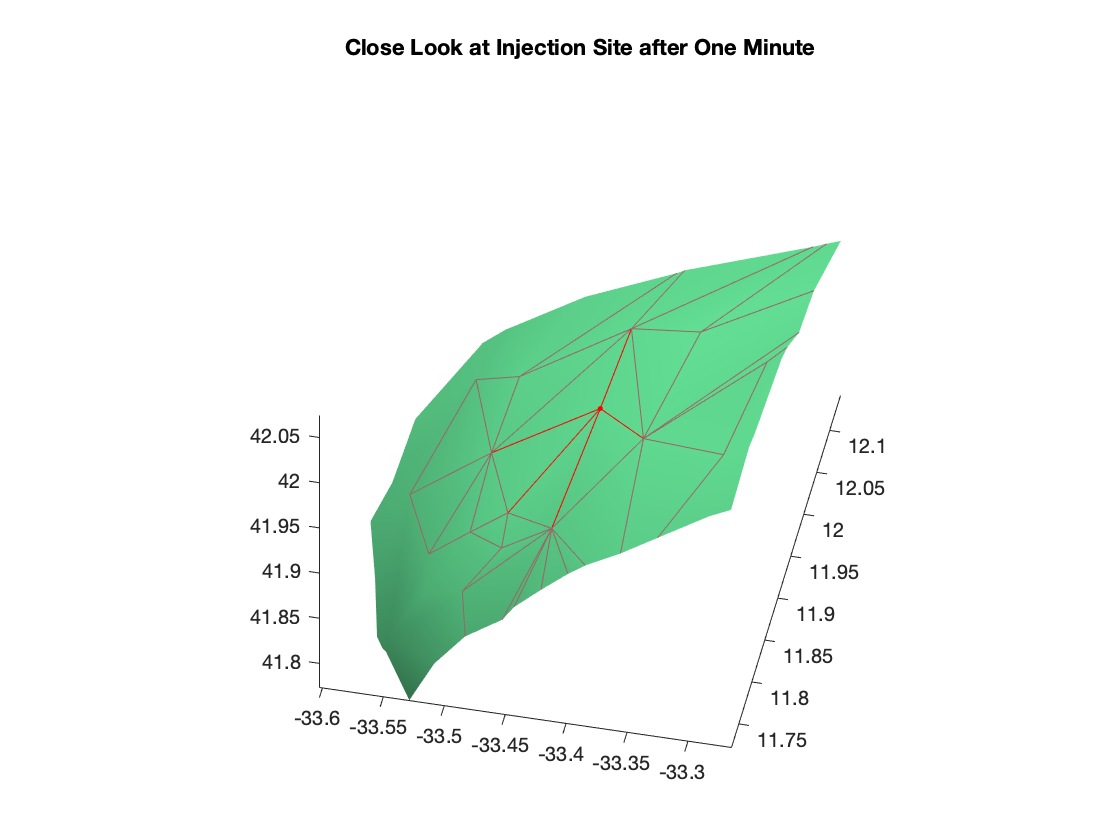

% Your code here
RedWeb(Faces_neighboring,vB,fB,[0.6 0.4 0.4])

f) (4 points) Apply the procedure 8 more times to determine the new faces that the innoculation will reach during the 10th minute after injection.  Store the list of faces in a column vector named  "Faces_n_faces_away".

% Your code here
F_n1 = find_neighbor(Faces_neighboring,fB,vB,[Faces_adjacent']);
F_n2 = find_neighbor(F_n1,fB,vB,[Faces_adjacent' F_n1]);
F_n3 = find_neighbor(F_n2,fB,vB,[Faces_adjacent' F_n1 F_n2]);
F_n4 = find_neighbor(F_n3,fB,vB,[Faces_adjacent' F_n1 F_n2 F_n3]);
F_n5 = find_neighbor(F_n4,fB,vB,[Faces_adjacent' F_n1 F_n2 F_n3 F_n4]);
F_n6 = find_neighbor(F_n5,fB,vB,[Faces_adjacent' F_n1 F_n2 F_n3 F_n4 F_n5]);
F_n7 = find_neighbor(F_n6,fB,vB,[Faces_adjacent' F_n1 F_n2 F_n3 F_n4 F_n5 F_n6]);
F_n8 = find_neighbor(F_n7,fB,vB,[Faces_adjacent' F_n1 F_n2 F_n3 F_n4 F_n5 F_n6 F_n7]);
Faces_n_faces_away = F_n8'

Faces_n_faces_away =       275707
      275708
      275709
      275710
      275711
      275712
      275713
      275716
      280622
      280623


function [U,f_hat]=g_e(K,f)
% Put your code here
    % calculate multiplication factor
    % factor * pivot row
    % add pivot row to current row
    
    % loop through j then i; perform same on f
    % find r = -curent start (i,j) / pivot (j,j)
    % pivot row = k(j,:)*r
    % current row k(i,:) = k(i,:) + pr
    n = size(K);
    U = K;
    f_hat = f;
    for j = 1:n-1
        for i = j+1:n
            r = -U(i,j)/U(j,j);
            f_hat(i) = f_hat(i)+f_hat(j)*r;
            U(i,:) = U(i,:)+U(j,:)*r;
        end
    end
end

function u=b_s(U,f_hat)
% U*u = f_hat
% []
% Put your code here
    n = length(f_hat);
    u = zeros(length(f_hat),1);
    u(n) = f_hat(n)/U(n,n);
    for i = n-1:-1:1
        %U(i,:)*u(:)=f_hat(i)
        %AKA U(i,i:n)*u(i:n)=f_hat(i)
        sum = f_hat(i);
        for j = n:-1:i+1
            sum = sum-U(i,j)*u(j);
        end
        u(i)=sum/U(i,i);
    end
end

function []=RedWeb(facelist,v,f,color)
    hold on
    for i = 1:length(facelist) %for each face_row#
        face_vtx_row = facelist(i); %relavent row# in fB
        this_face = f(face_vtx_row,:); %face
        pt1 = v(this_face(1),:);
        pt2 = v(this_face(2),:);
        pt3 = v(this_face(3),:);
        line([pt1(1) pt2(1)], [pt1(2) pt2(2)], [pt1(3) pt2(3)],'Color',color)
        line([pt1(1) pt3(1)], [pt1(2) pt3(2)], [pt1(3) pt3(3)],'Color',color)
        line([pt3(1) pt2(1)], [pt3(2) pt2(2)], [pt3(3) pt2(3)],'Color',color)
    end

end

function [v, f, n] = stlReadBinary(fileName)
% adapted from stlTools version 1.1.0.0 (1.58 MB) by Pau Micó
%STLREADBINARY reads a STL file written in BINARY format
%V are the vertices
%F are the faces
%N are the normals
%=======================
% STL binary file format
%=======================
% Binary STL files have an 84 byte header followed by 50-byte records, each
% describing a single facet of the mesh.  Technically each facet could be
% any 2D shape, but that would screw up the 50-byte-per-facet structure, so
% in practice only triangular facets are used.  The present code ONLY works
% for meshes composed of triangular facets.
%
% HEADER:
% 80 bytes:  Header text
% 4 bytes:   (int) The number of facets in the STL mesh
%
% DATA:
% 4 bytes:  (float) normal x
% 4 bytes:  (float) normal y
% 4 bytes:  (float) normal z
% 4 bytes:  (float) vertex1 x
% 4 bytes:  (float) vertex1 y
% 4 bytes:  (float) vertex1 z
% 4 bytes:  (float) vertex2 x
% 4 bytes:  (float) vertex2 y
% 4 bytes:  (float) vertex2 z
% 4 bytes:  (float) vertex3 x
% 4 bytes:  (float) vertex3 y
% 4 bytes:  (float) vertex3 z
% 2 bytes:  Padding to make the data for each facet 50-bytes in length
%   ...and repeat for next facet... 
fid = fopen(fileName);
header = fread(fid,80,'int8'); % reading header's 80 bytes
name = deblank(native2unicode(header,'ascii')');
if isempty(name)
    name = 'Unnamed Object'; % no object name in binary files!
end
nfaces = fread(fid,1,'int32');  % reading the number of facets in the stl file (next 4 byters)
nvert = 3*nfaces; % number of vertices
% reserve memory for vectors (increase the processing speed)
n = zeros(nfaces,3);
v = zeros(nvert,3);
f = zeros(nfaces,3);
for i = 1 : nfaces % read the data for each facet
    tmp = fread(fid,3*4,'float'); % read coordinates
    n(i,:) = tmp(1:3); % x,y,z components of the facet's normal vector
    v(3*i-2,:) = tmp(4:6); % x,y,z coordinates of vertex 1
    v(3*i-1,:) = tmp(7:9); % x,y,z coordinates of vertex 2
    v(3*i,:) = tmp(10:12); % x,y,z coordinates of vertex 3
    f(i,:) = [3*i-2 3*i-1 3*i]; % face
    fread(fid,1,'int16'); % Move to the start of the next facet (2 bytes of padding)
end
fclose(fid);
% slim the file (delete duplicated vertices)
[v,f] = stlSlimVerts(v,f);
end


function [vnew, fnew]= stlSlimVerts(v, f)
% PATCHSLIM removes duplicate vertices in surface meshes.
% 
% This function finds and removes duplicate vertices.
%
% USAGE: [v, f]=patchslim(v, f)
%
% Where v is the vertex list and f is the face list specifying vertex
% connectivity.
%
% v contains the vertices for all triangles [3*n x 3].
% f contains the vertex lists defining each triangle face [n x 3].
%
% This will reduce the size of typical v matrix by about a factor of 6.
%
% For more information see:
%  http://www.esmonde-white.com/home/diversions/matlab-program-for-loading-stl-files
%
% Francis Esmonde-White, May 2010
if ~exist('v','var')
    error('The vertex list (v) must be specified.');
end
if ~exist('f','var')
    error('The vertex connectivity of the triangle faces (f) must be specified.');
end
[vnew, indexm, indexn] =  unique(v, 'rows');
fnew = indexn(f);
end

function stlPlot(v, f, color)
%STLPLOT is an easy way to plot an STL object
%V is the Nx3 array of vertices
%F is the Mx3 array of faces
%NAME is the name of the object, that will be displayed as a title
object.vertices = v;
object.faces = f;
patch(object,'FaceColor',       [0.4 0.9 0.6], ...
         'EdgeColor',       'none',        ...
         'FaceLighting',    'gouraud',     ...
         'AmbientStrength', 0.15);
% Add a camera light, and tone down the specular highlighting
camlight('headlight');
material('dull');
axis('image');
end

function Faces_neighboring = find_neighbor(Faces_adjacent,fB,vB,prevs)
    pt_rws = zeros(3*length(Faces_adjacent),1);
    Faces_near = [];
    for i = 1:length(Faces_adjacent)
        this_face = fB(Faces_adjacent(i),:);
        pt_rws(3*i-2) = this_face(1);
        pt_rws(3*i-1) = this_face(2);
        pt_rws(3*i) = this_face(3);
    end
    for i = 1:length(fB)
        face = fB(i,:);
        for j = 1:3 %for the three vertices of the triangle
            for pti = 1:length(pt_rws) %for each pt index in pt_rws
                if face(j)==pt_rws(pti) %if a pt_rw in face== pt_rw in pt_rws
                    in_near = 0;
                    for k = 1:length(Faces_near)
                        if ~in_near && i==Faces_near(k)
                            in_near = 1;
                        end
                    end
                    for k = 1:length(prevs)
                        if ~in_near && i==prevs(k)
                            in_near = 1;
                        end
                    end
                    if ~in_near
                        Faces_near = [Faces_near i];
                    end
                end
            end
        end
    end
    Faces_neighboring = [];
    for i = 1:length(Faces_near)
        in_adj = 0;
        for j = 1:length(Faces_adjacent)
            if Faces_near(i)==Faces_adjacent(j)
                in_adj = 1;
            end
        end
        if ~in_adj
            Faces_neighboring = [Faces_neighboring Faces_near(i)];
        end
    end
end